# Lecture 5: Histogram Processing

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture5 - Histogram Processing

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

## Image histograms

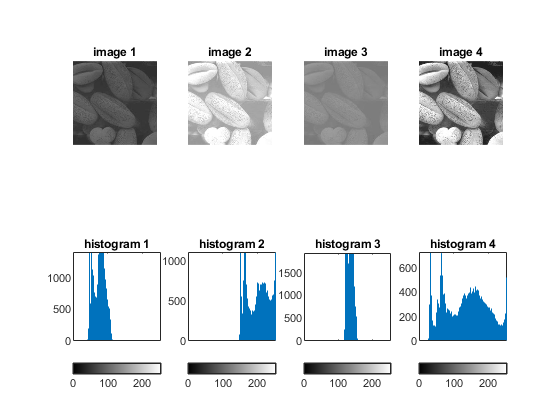

% read image files
I1 = imread('images/1.jpg');
I2 = imread('images/2.jpg');
I3 = imread('images/3.jpg');
I4 = imread('images/4.jpg');

% plot images and their histograms
figure, subplot(2,4,1), imshow(I1), title('image 1');
subplot(2,4,2), imshow(I2), title('image 2');
subplot(2,4,3), imshow(I3), title('image 3');
subplot(2,4,4), imshow(I4), title('image 4');
subplot(2,4,5), imhist(I1), title('histogram 1'), axis square;
subplot(2,4,6), imhist(I2), title('histogram 2'), axis square;
subplot(2,4,7), imhist(I3), title('histogram 3'), axis square;
subplot(2,4,8), imhist(I4), title('histogram 4'), axis square;

## Histogram equalization

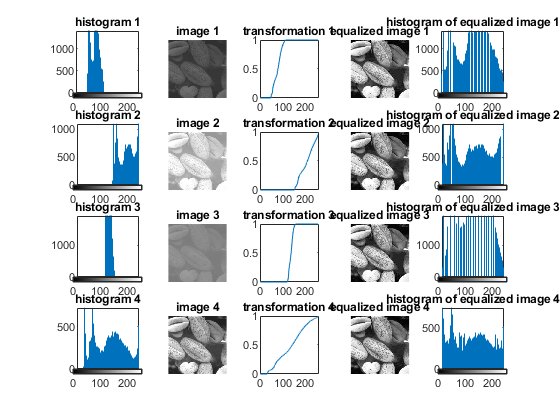

[I1_equalized, T1] = histeq(I1,256);
[I2_equalized, T2] = histeq(I2,256);
[I3_equalized, T3] = histeq(I3,256);
[I4_equalized, T4] = histeq(I4,256);

figure, subplot(4,5,1), imhist(I1), title('histogram 1'), axis square;
subplot(4,5,2), imshow(I1), title('image 1');
subplot(4,5,3), plot(T1), title('transformation 1'), axis([0 255 0 1]), axis square;
subplot(4,5,4), imshow(I1_equalized), title('equalized image 1');
subplot(4,5,5), imhist(I1_equalized), title('histogram of equalized image 1'), axis square;

subplot(4,5,6), imhist(I2), title('histogram 2'), axis square;
subplot(4,5,7), imshow(I2), title('image 2');
subplot(4,5,8), plot(T2), title('transformation 2'), axis([0 255 0 1]), axis square;
subplot(4,5,9), imshow(I2_equalized), title('equalized image 2');
subplot(4,5,10), imhist(I2_equalized), title('histogram of equalized image 2'), axis square;

subplot(4,5,11), imhist(I3), title('histogram 3'), axis square;
subplot(4,5,12), imshow(I3), title('image 3');
subplot(4,5,13), plot(T3), title('transformation 3'), axis([0 255 0 1]), axis square;
subplot(4,5,14), imshow(I3_equalized), title('equalized image 3');
subplot(4,5,15), imhist(I3_equalized), title('histogram of equalized image 3'), axis square;

subplot(4,5,16), imhist(I4), title('histogram 4'), axis square;
subplot(4,5,17), imshow(I4), title('image 4');
subplot(4,5,18), plot(T4), title('transformation 4'), axis([0 255 0 1]), axis square;
subplot(4,5,19), imshow(I4_equalized), title('equalized image 4');
subplot(4,5,20), imhist(I4_equalized), title('histogram of equalized image 4'), axis square;

## Adaptive histogram equalization

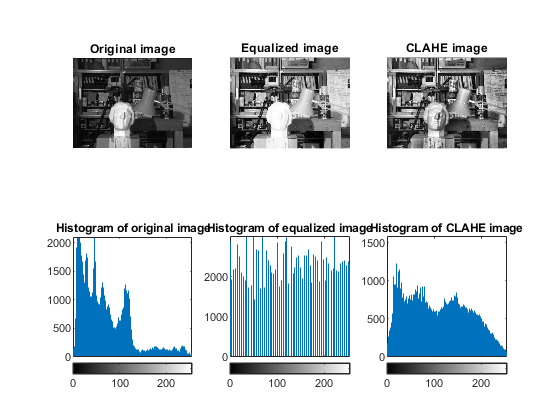

I = imread('images/image.jpg');
Ieq = histeq(I);
Ieq_adaptive = adapthisteq(I);

figure, subplot(2,3,1), imshow(I), title('Original image');
subplot(2,3,2), imshow(Ieq), title('Equalized image');
subplot(2,3,3), imshow(Ieq_adaptive), title('CLAHE image');
subplot(2,3,4), imhist(I), title('Histogram of original image'), axis square;
subplot(2,3,5), imhist(Ieq), title('Histogram of equalized image'), axis square;
subplot(2,3,6), imhist(Ieq_adaptive), title('Histogram of CLAHE image'), axis square;